# **Project One Template**

## MAT350: Applied Linear Algebra

## *Nicholas Kreuziger*

## *1/23/2023*

# **Problem 1**

**Develop a system of linear equations for the network **by writing an equation for each router (A, B, C, D, and E). Make sure to write your final answer as A**x**=**b** where A is the 5x5 coefficient matrix, **x** is the 5x1 vector of unknowns, and **b** is a 5x1 vector of constants.

### Solution:

*Put your math/explanation here..*

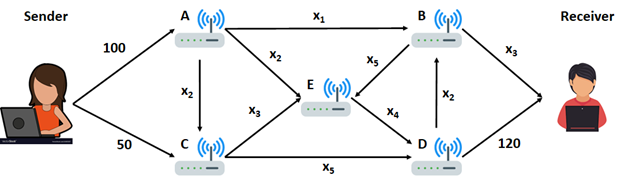

*A system of equations must be derived that summarizes the node traffic for each node. The equation's initial setup is "Flow Output = Flow Input". Following setup, simplification of the equation to place unknowns to the left-side and constants to the right-side. *

***Node A:***


$$x_1 +2x_2 =100$$


**Node B:**


$$x_3 +x_5 =x_1 +x_2$$


$-x_1 +-x_2 +$$x_3 +x_5 =$0

**Node C:**


$$x_3 +x_5 =50+x_2$$



$$-x_2 +$$

$$x_3 +x_5 =50$$


**Node D:**


$$x_2 +120=x_4 +x_5$$



$$-x_2 +x_4 +x_5 =120$$


**Node E:**


$$x_4 =x_2 +x_3 +x_5$$



$$x_2 +x_3 -x_4 +x_5 =0$$


A = [

1 2 0 0 0;

-1 -1 1 0 1;

0 -1 1 0 1;

0 -1 0 1 1;

0 1 1 -1 1

]

x=[

$x_1$;

$x_2$;

$x_3$;

$x_4$;

$x_5$;

]

b = [

100;

0;

50;

120;

0

]

# **Problem 2**

Use MATLAB to construct the augmented matrix [A **b**] and then perform row reduction using the rref() function. Write out your **reduced matrix and identify the free and basic variables of the system**.

### Solution:

%code
A = [
    1 2 0 0 0;
    -1 -1 1 0 1;
    0 -1 1 0 1;
    0 -1 0 1 1;
    0 1 1 -1 1
    ]

A =      1     2     0     0     0
    -1    -1     1     0     1
     0    -1     1     0     1
     0    -1     0     1     1
     0     1     1    -1     1


b = [
    100;
    0;
    50;
    120;
    0
    ]

b =    100
     0
    50
   120
     0



Ab = [A b]

Ab =      1     2     0     0     0   100
    -1    -1     1     0     1     0
     0    -1     1     0     1    50
     0    -1     0     1     1   120
     0     1     1    -1     1     0



ech_Ab = rref(Ab)

ech_Ab =      1     0     0     0     0    50
     0     1     0     0     0    25
     0     0     1     0     0    30
     0     0     0     1     0   100
     0     0     0     0     1    45



%A basic variable is a variable with a leading coefficient 1 , whereas a
%free variable is a variable without a pivot. There are no free variables
%in this system since every column preceding constants is a pivot column.

# **Problem 3**

Use MATLAB to **compute the LU decomposition of A**, i.e., find A = LU. For this decomposition, find the transformed set of equations L**y** = **b**, where **y** = U**x**. Solve the system of equations L**y** = **b** for the unknown vector **y**.

### Solution:

%code
%Initiate the coefficient matrix A & column of constants matrix b
A = [
    1 2 0 0 0;
    -1 -1 1 0 1;
    0 -1 1 0 1;
    0 -1 0 1 1;
    0 1 1 -1 1
    ]

A =      1     2     0     0     0
    -1    -1     1     0     1
     0    -1     1     0     1
     0    -1     0     1     1
     0     1     1    -1     1


b = [
    100;
    0;
    50;
    120;
    0
    ]

b =    100
     0
    50
   120
     0


%use LU command
[L, U] = lu(A)

L =     1.0000         0         0         0         0
   -1.0000    1.0000         0         0         0
         0   -1.0000    1.0000         0         0
         0   -1.0000    0.5000    1.0000         0
         0    1.0000         0   -1.0000    1.0000


U =      1     2     0     0     0
     0     1     1     0     1
     0     0     2     0     2
     0     0     0     1     1
     0     0     0     0     1



%solve using system of linear equations Ax=b. store solutions x & y
y = L\b

y =    100
   100
   150
   145
    45


# **Problem 4**

Use MATLAB to **compute the inverse **of U using the inv() function.

### Solution:

%code
inv(U)

ans =     1.0000   -2.0000    1.0000         0         0
         0    1.0000   -0.5000         0         0
         0         0    0.5000         0   -1.0000
         0         0         0    1.0000   -1.0000
         0         0         0         0    1.0000


# **Problem 5**

**Compute the solution to the original system of equations **by transforming **y **into **x**, i.e., compute **x** = inv(U)**y**.

### Solution:

%code
x = inv(U)*y

x =     50
    25
    30
   100
    45


# **Problem 6**

**Check your answer for **$x_{1}$ **using Cramer’s Rule.** Use MATLAB to compute the required determinants using the det() function. 

### Solution:

%code
%checking all answers to be thorough :) 
A = [
    1 2 0 0 0;
    -1 -1 1 0 1;
    0 -1 1 0 1;
    0 -1 0 1 1;
    0 1 1 -1 1
    ]

A =      1     2     0     0     0
    -1    -1     1     0     1
     0    -1     1     0     1
     0    -1     0     1     1
     0     1     1    -1     1



b = [
    100;
    0;
    50;
    120;
    0
    ]

b =    100
     0
    50
   120
     0


%Initialize the matrices A1, A2, and A3 as matrix A.
A1 = A

A1 =      1     2     0     0     0
    -1    -1     1     0     1
     0    -1     1     0     1
     0    -1     0     1     1
     0     1     1    -1     1


A2 = A

A2 =      1     2     0     0     0
    -1    -1     1     0     1
     0    -1     1     0     1
     0    -1     0     1     1
     0     1     1    -1     1


A3 = A

A3 =      1     2     0     0     0
    -1    -1     1     0     1
     0    -1     1     0     1
     0    -1     0     1     1
     0     1     1    -1     1


A4 = A

A4 =      1     2     0     0     0
    -1    -1     1     0     1
     0    -1     1     0     1
     0    -1     0     1     1
     0     1     1    -1     1


A5 = A

A5 =      1     2     0     0     0
    -1    -1     1     0     1
     0    -1     1     0     1
     0    -1     0     1     1
     0     1     1    -1     1


%Replace the appropriate columns in A1, A2, and A3 with the column vector of constants b. 
A1(:,1)=b

A1 =    100     2     0     0     0
     0    -1     1     0     1
    50    -1     1     0     1
   120    -1     0     1     1
     0     1     1    -1     1


A2(:,2)=b

A2 =      1   100     0     0     0
    -1     0     1     0     1
     0    50     1     0     1
     0   120     0     1     1
     0     0     1    -1     1


A3(:,3)=b

A3 =      1     2   100     0     0
    -1    -1     0     0     1
     0    -1    50     0     1
     0    -1   120     1     1
     0     1     0    -1     1


A4(:,4)=b

A4 =      1     2     0   100     0
    -1    -1     1     0     1
     0    -1     1    50     1
     0    -1     0   120     1
     0     1     1     0     1


A5(:,5)=b

A5 =      1     2     0     0   100
    -1    -1     1     0     0
     0    -1     1     0    50
     0    -1     0     1   120
     0     1     1    -1     0


%Find the solution for x1, x2, and x3 using ratios of determinants.
x1 = det(A1)/det(A)

x1 = 50

x2 = det(A2)/det(A)

x2 = 25

x3 = det(A3)/det(A)

x3 = 30.0000

x4 = det(A4)/det(A)

x4 = 100

x5 = det(A5)/det(A)

x5 = 45

# **Problem 7**

The Project One Table Template, provided in the Project One Supporting Materials section in Brightspace, shows the recommended throughput capacity of each link in the network. Put your solution for the system of equations in the third column so it can be easily compared to the maximum capacity in the second column. In the fourth column of the table, provide recommendations for how the network should be modified based on your network throughput analysis findings. The modification options can be No Change, Remove Link, or Upgrade Link. In the final column, explain how you arrived at your recommendation.

### Solution:

   *Fill out the table in the original project document and export your table as an image. Then, use the ****Insert**** tab in the MATLAB editor to insert your table as an image.*